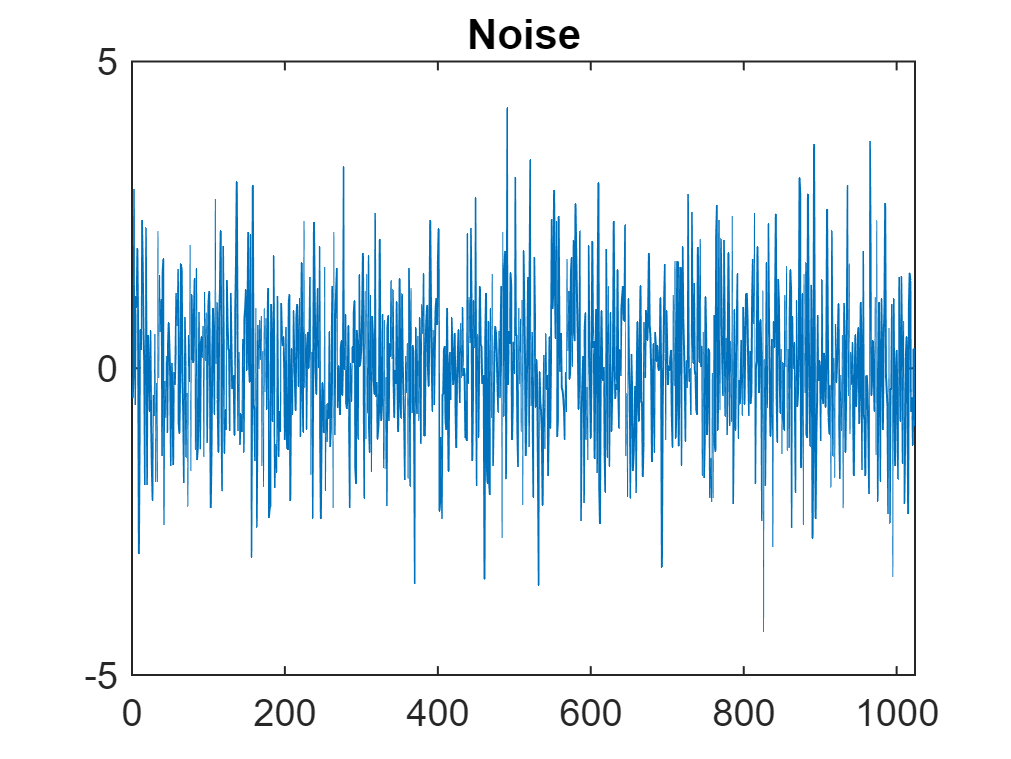

noiseVar = 1.5;

N = 1024;
M = 16;
D = M/2;
L = N/M;
fs = 10000;
noise = wgn(1,N,noiseVar,'linear');
plot(noise)
title("Noise")

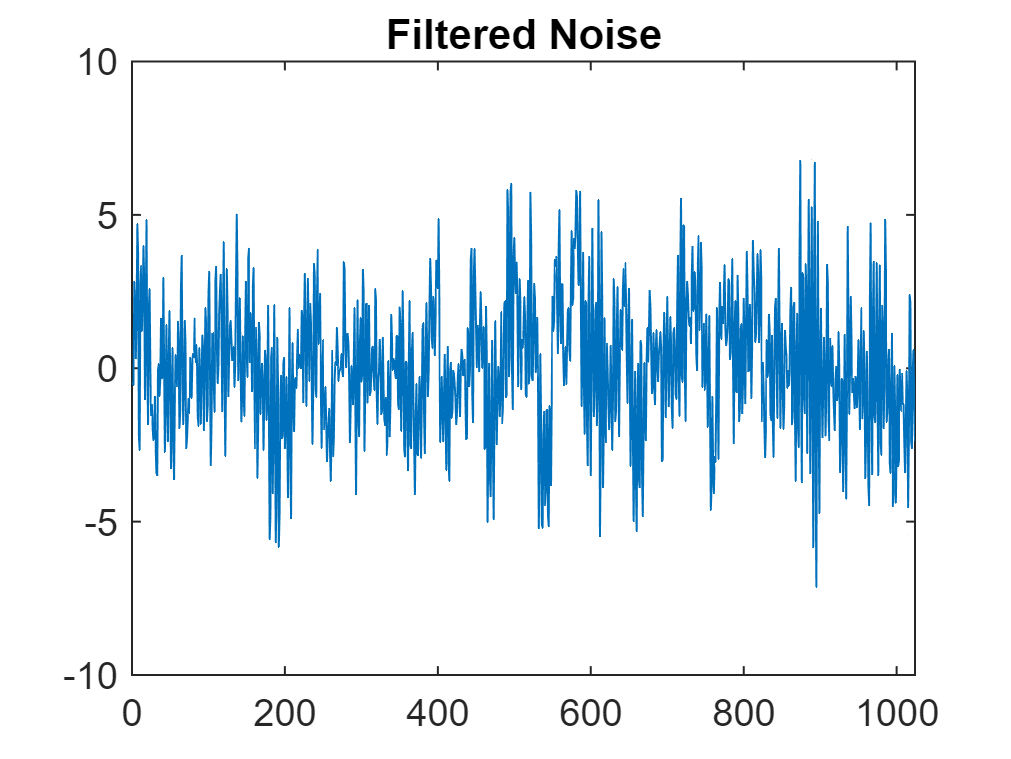


b = 1;
a = [1 -0.9 0.81 -0.729];
x = filter(b,a,noise,[],2);
plot(x)
title("Filtered Noise")

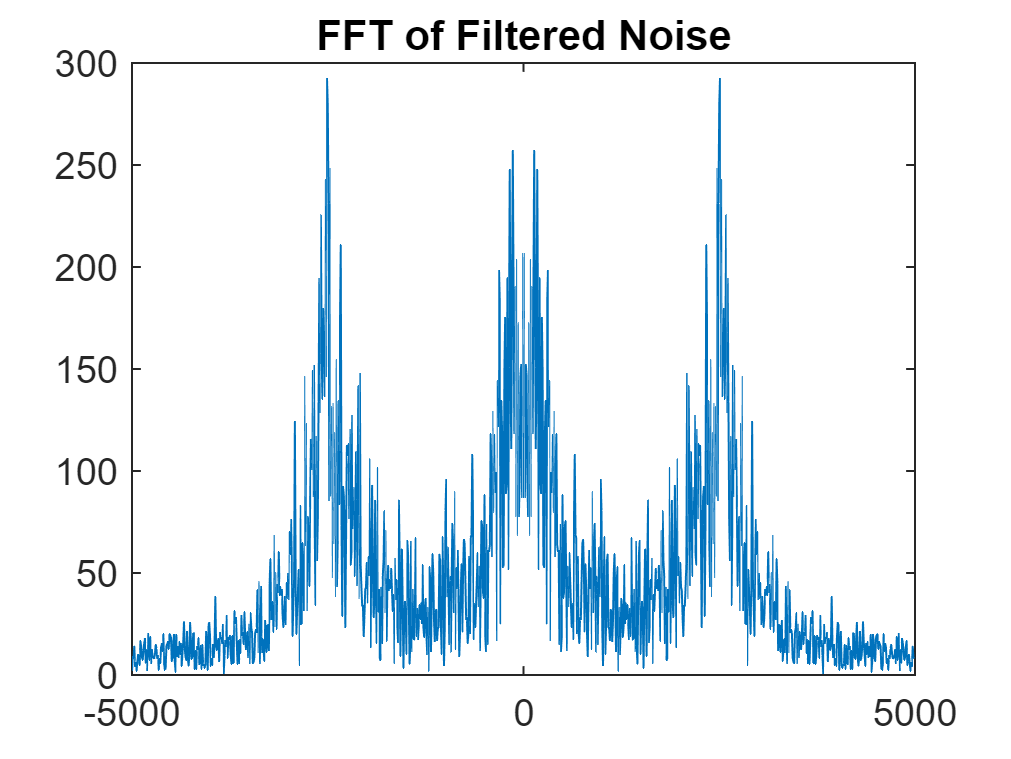


y = abs(fftshift(fft(x)));
f = (-N/2: N/2 - 1)*(fs/N);
plot(f,y);
title("FFT of Filtered Noise")


x_mat = zeros(M,L);
for i = 1:L
    x_mat(:,i) = x((i-1)*(M)+1: i*M);
end

%50% overlapping
L = N/(2*M) -1;
x_mat = zeros(M, L );
for i = 1:L
    x_mat(:,i) = x((i-1)*(M/2)+1: (i+1)*M/2);
end

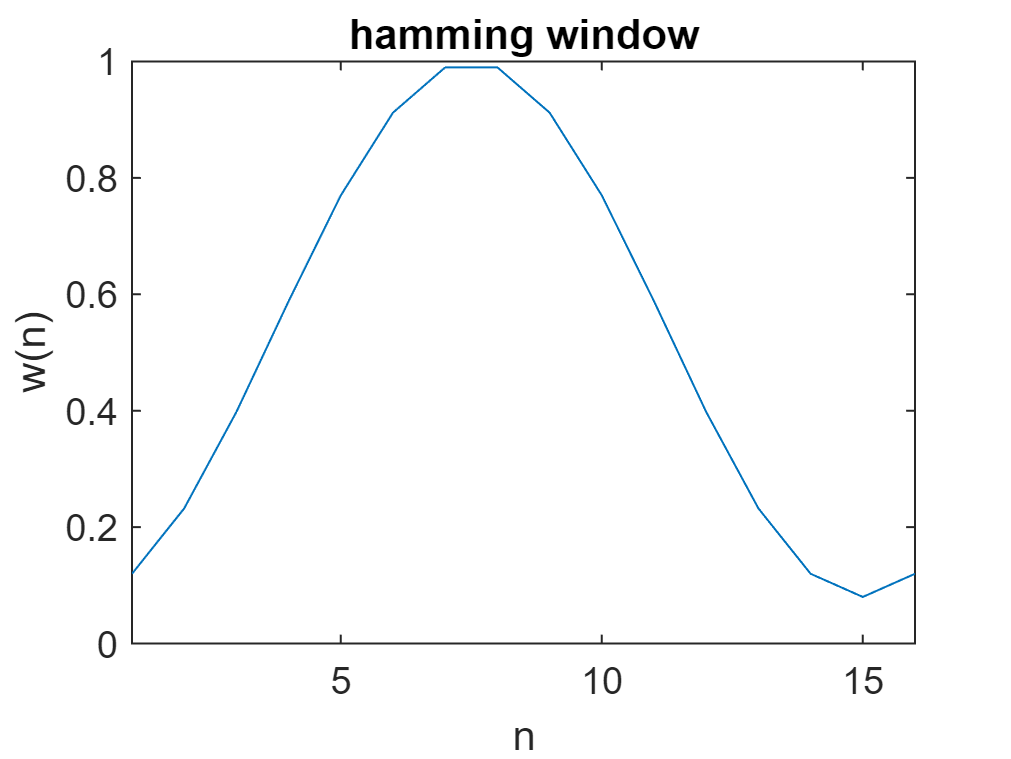

%hamming window
w = zeros(1,M);
for i=1:M
    w(i)=0.54-0.46*cos((2*pi*i)/(M-1));
end
plot(w);
xlabel('n')
ylabel('w(n)')
xlim([1 M])
title('Hamming window')

summation = 0;
for i = 1:M
    summation = summation + w(i)^2;
end
U = (1/M)*summation;

f = -1*(fs/2):fs/M:(fs/2)-1;
P = zeros(length(f), L);
for i=1:L
    sum = 0;
    for n = 1:M
        sum = sum + x_mat(n, i)*w(n)*exp(-1i*2*pi*f*n/M);
    end
    P(:,i) = (1/(M*U))*(abs(sum).^2);
end

sum2 = 0;
for i = 1:L
    sum2 = sum2 + P(:, i);
end
PSD = (1/L)*sum2;

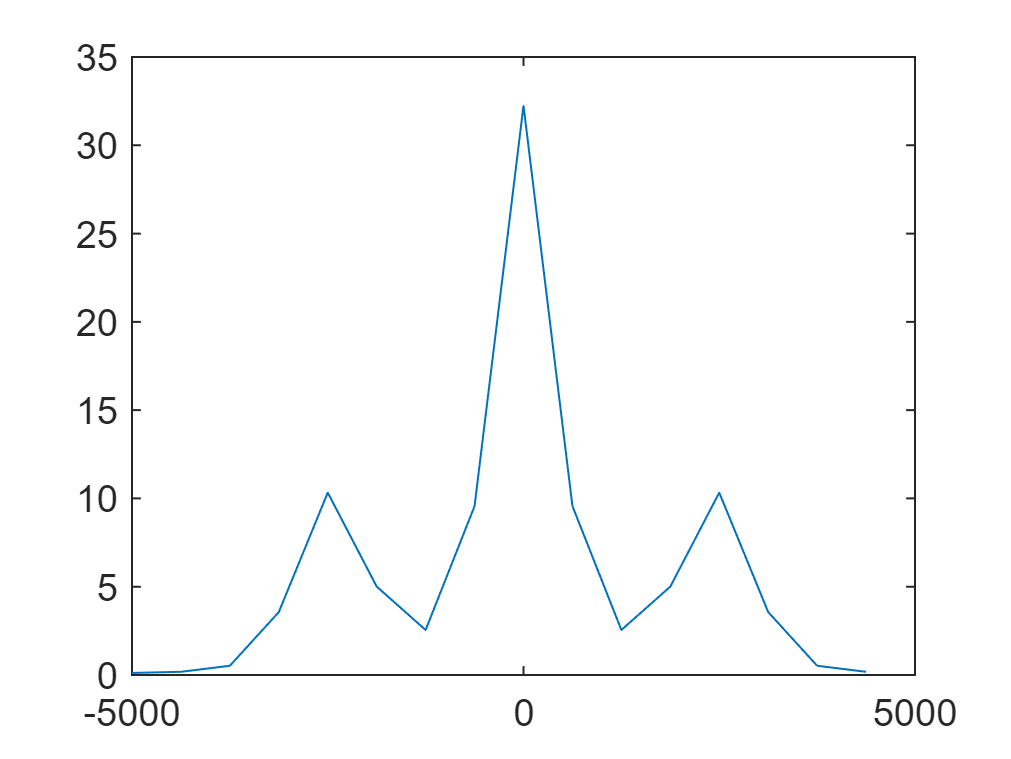

plot(f, PSD)

title("PSD of the sequence")

p=3;
r = zeros(p+1, 1);
for m = 1:p+1
    sum2 = 0;
    for n = 1:N-m
        sum2 = sum2 + x(n)*x(n+m-1);
    end
    r(m) = (1/N)*sum2;
end
r_mat = zeros(p,p);
for i = 1:p
    for k = 1:p
        r_mat(i, k) = r(abs(i-k)+1);
    end
end

a = -inv(r_mat)*r(2:p+1,1)

a =    -0.9537
    0.8118
   -0.7174


summation2 = 0;
for i = 2:p+1
    summation2 = summation2 + a(i-1)*r(i);
end
estimated_variance = r(1) + summation2

estimated_variance = 1.5063

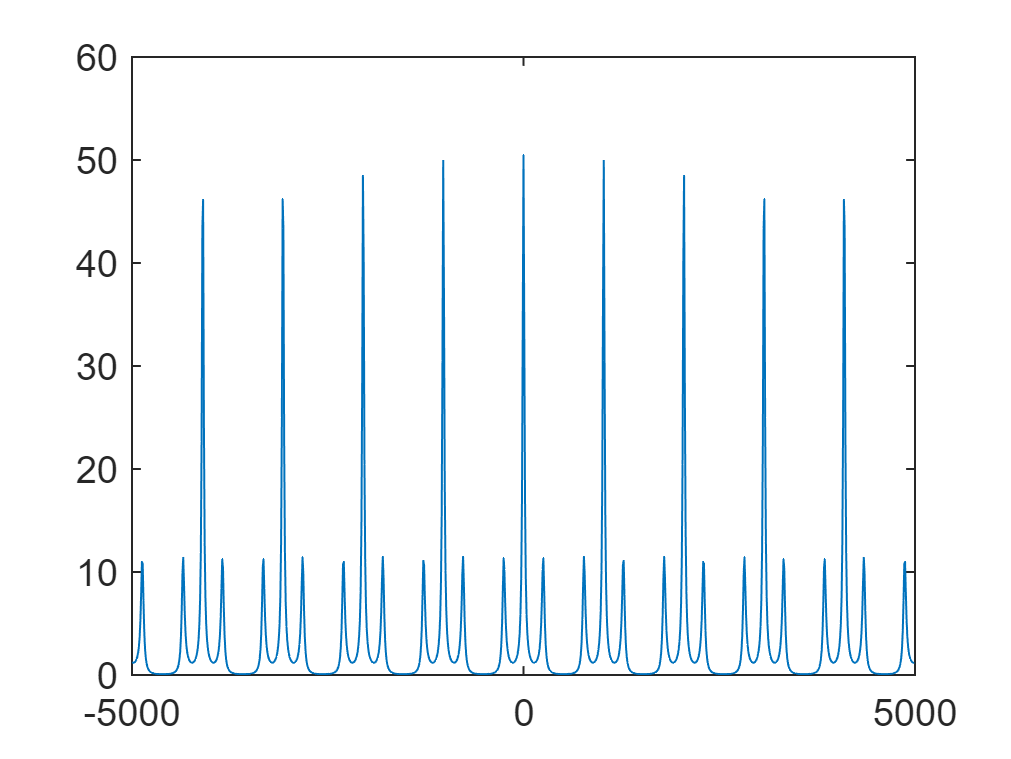

f2 = -1*(fs/2):fs/N:(fs/2)-1;
z = exp(1i*2*pi*f2/N);
sum = zeros(1, N);
for k = 1:N
    for i = 1:p
        sum(k) = sum(k) + a(i)*(z(k).^(-i)) ;
    end
end

H = 1./(1+sum);
psd2 = abs(H).^2;
plot(f2, psd2)